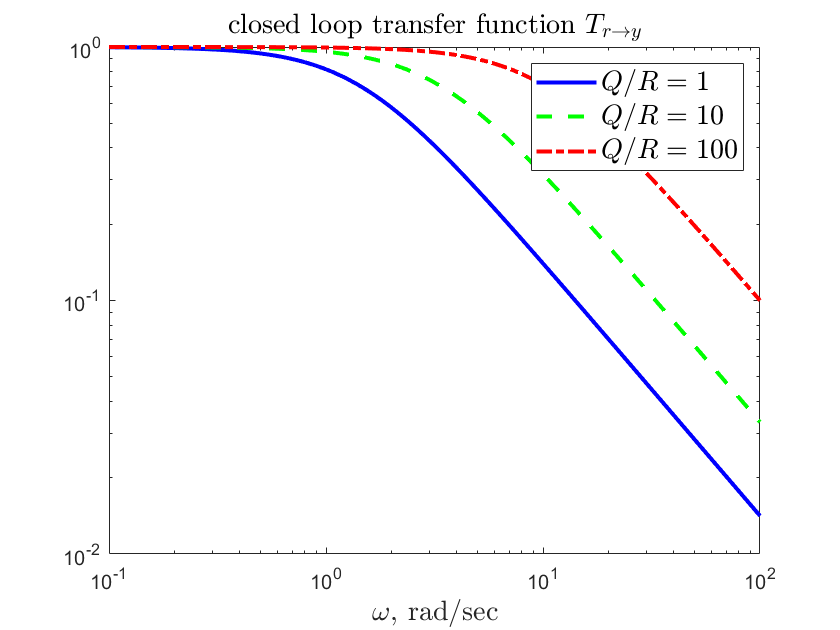

%% Part (f)

A = 1;
B= 1;
C= 1;
 
Q= 1;
R= 1;
s = tf('s');

K = lqr(A,B,Q,R);
G = - (A - B*K) / (B*C);
Try = G*B*C / (s - (A-B*K));

w = logspace(-1,2,200);

figure(1)
clf

[mag,~] = bode(Try,w);
loglog(w,squeeze(mag),'b-')

hold on


Q=10;
R=1;

K = lqr(A,B,Q,R);
G = - (A - B*K) / (B*C);
Try = G*B*C / (s - (A-B*K));

[mag,~] = bode(Try,w);
loglog(w,squeeze(mag),'g--')


Q=100;
R=1;

K = lqr(A,B,Q,R);
G = - (A - B*K) / (B*C);
Try = G*B*C / (s - (A-B*K));

[mag,~] = bode(Try,w);
loglog(w,squeeze(mag),'r-.')
h = title('closed loop transfer function $T_{r\rightarrow y}$');
hh = xlabel('$\omega$, rad/sec');
hhh = legend('$Q/R=1$','$Q/R=10$','$Q/R=100$');
set(h,'interpreter','latex','fontsize',14);
set(hh,'interpreter','latex','fontsize',14);
set(hhh,'interpreter','latex','fontsize',14);
set(findall(gcf,'type','line'),'linewidth',2)
hold off

Transfer function from r to u  ( Tru ) 

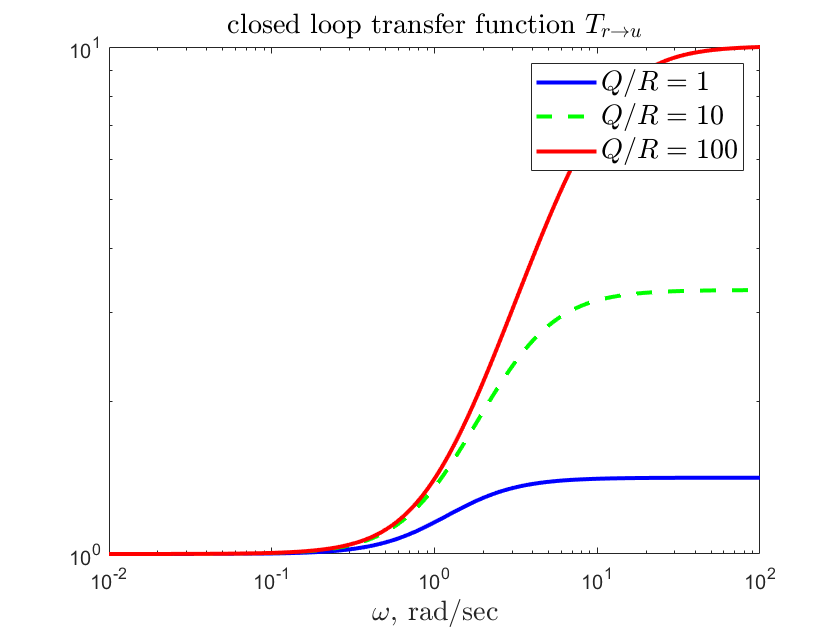



figure(2)
clf

Q= 1;
R= 1;

K = lqr(A,B,Q,R);

G = - (A - B*K) / (B*C);
Tru = (s - A) / (B*C) * G*B*C / (s - (A-B*K)); 
w = logspace(-2,2,200);
[mag,~] = bode(Tru, w);
loglog(w,squeeze(mag),'b-');

hold on 

Q= 10;
R= 1;

K = lqr(A,B,Q,R);

G = - (A - B*K) / (B*C);
Tru = (s - A) / (B*C) * G*B*C / (s - (A-B*K)); 
w = logspace(-2,2,200);
[mag,~] = bode(Tru, w);
loglog(w,squeeze(mag),'g--');

hold on 

Q= 100;
R= 1;

K = lqr(A,B,Q,R);

G = - (A - B*K) / (B*C);
Tru = (s - A) / (B*C) * G*B*C / (s - (A-B*K)); 
w = logspace(-2,2,200);
[mag,~] = bode(Tru, w);
loglog(w,squeeze(mag),'r-');

h = title('closed loop transfer function $T_{r\rightarrow u}$');
hh = xlabel('$\omega$, rad/sec');
hhh = legend('$Q/R=1$','$Q/R=10$','$Q/R=100$');
set(h,'interpreter','latex','fontsize',14);
set(hh,'interpreter','latex','fontsize',14);
set(hhh,'interpreter','latex','fontsize',14);
set(findall(gcf,'type','line'),'linewidth',2)
hold off

Show step response of y and u  

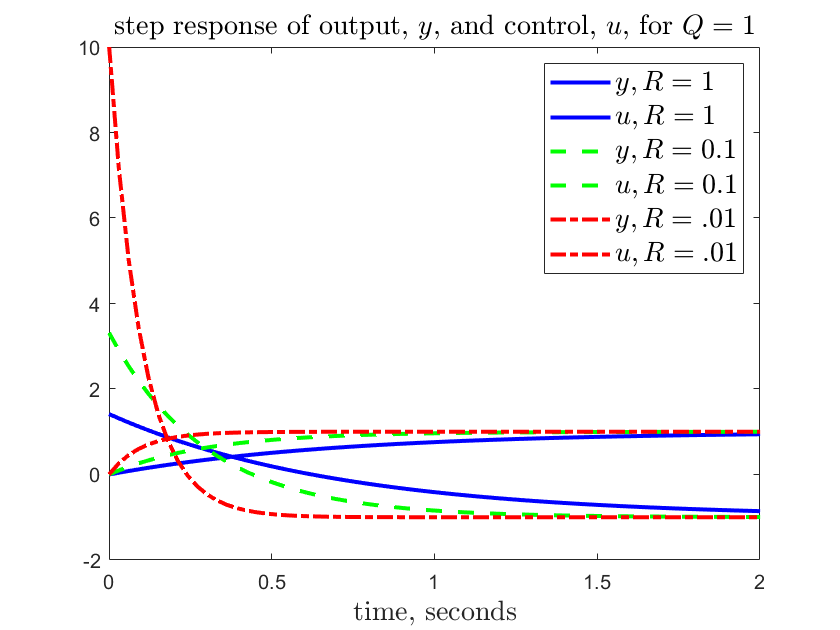

t = linspace(0,3,100);

Q= 1;
R= 1;

K =  lqr(A,B,Q,R);

G = - (A - B*K) / (B*C);
Try1 = G*B*C / (s - (A-B*K));
Tru1 = (s - A) / (B*C) * G*B*C / (s - (A-B*K));
y1 = step(Try1,t);
u1 = step(Tru1,t);


% change for different R 
R= 0.1;

K =  lqr(A,B,Q,R);

G = - (A - B*K) / (B*C);
Try2 = G*B*C / (s - (A-B*K));
Tru2 = (s - A) / (B*C) * G*B*C / (s - (A-B*K));
y2 = step(Try2,t);
u2 = step(Tru2,t);

R= 0.01;

K =  lqr(A,B,Q,R);

G = - (A - B*K) / (B*C);
Try3 = G*B*C / (s - (A-B*K));
Tru3 = (s - A) / (B*C) * G*B*C / (s - (A-B*K));
y3 = step(Try3,t);
u3 = step(Tru3,t);

figure(3)
clf
 
plot(t,y1,'b-',t,u1,'b-',t,y2,'g--',t,u2,'g--',t,y3,'r-.',t,u3,'r-.')
axis([0 2 -2 10])
h = xlabel('time, seconds');
hh = title('step response of output, $y$, and control, $u$, for $Q=1$');
hhh = legend('$y, R=1$','$u, R=1$','$y, R=0.1$','$u, R=0.1$','$y, R=.01$','$u, R=.01$');
set(h,'interpreter','latex','fontsize',14);
set(hh,'interpreter','latex','fontsize',14);
set(hhh,'interpreter','latex','fontsize',14);
set(findall(gcf,'type','line'),'linewidth',2)